# `5. Измерения и наблюдаемые`

## `5.1. Поляроид`

`Если на пути фотона поставить идеальный фотодетектор, то он его зарегистрирует с вероятностью 1 ( щелчок, рис. 7). Если же фотона нет, щелчка не будет.`

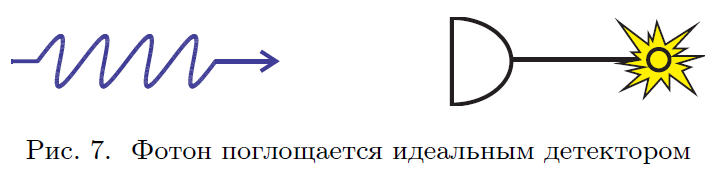

`Проведем аналогичный опыт, но на пути фотона поставим поляроид. Для макроскопической электромагнитной волны поляроид, ориентированный вдоль некоторого направления, на выходе выдает компоненту волны с поляризацией вдоль этого направления, а перпендикулярную компоненту поглощает.`

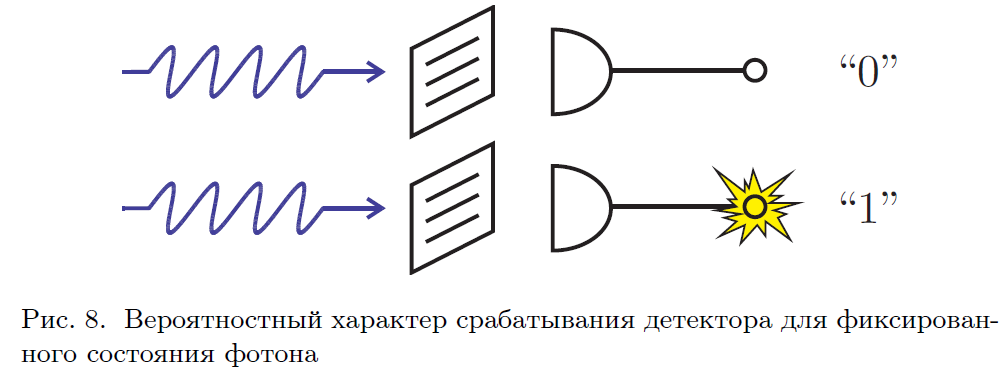

`Единственными случаями, когда результат можно предсказать, являются случаи линейной поляризации вдоль и попер к оси поляроида: в первом случае фотон детектируется с вероятностью 1, во втором с вероятностью 0.`

`Дело в том, что поляроид проецирует состояния и может выдавать на выходе фотоны только с поляризацией вдоль этого направления. Например, если поляроид ориентирован горизонтально, то на выходе из него все пролетающие фотоны находятся в состоянии `$|H\rangle$` (рис. 9).`

`Действие такого поляроида задается проектором`

clear
ketH=[1;0]

ketH =      1
     0


P=ketH*ketH'                   % (13)

P =      1     0
     0     0


`Подействуем этим проектором на произвольное состояние фотона`

$|\psi \rangle =c_1 |H\rangle +c_2 |V\rangle$:

$P|\psi \rangle =|H\rangle \langle H||\psi \rangle =|H\rangle \langle H|\psi \rangle =\langle H|\psi \rangle |H\rangle =c_1 |H\rangle =\left\lbrack \begin{array}{c}
c_1 \\
0
\end{array}\right\rbrack$          (14)

syms c1 c2
ketH=[1;0];ketV=[0;1]

ketV =      0
     1


ketpsi=c1*ketH+c2*ketV

$$ketpsi = \left(\begin{array}{c} c_{1}\\ c_{2} \end{array}\right)$$

P=[1 0;0 0]

P =      1     0
     0     0


P*ketpsi

$$ans = \left(\begin{array}{c} c_{1}\\ 0 \end{array}\right)$$

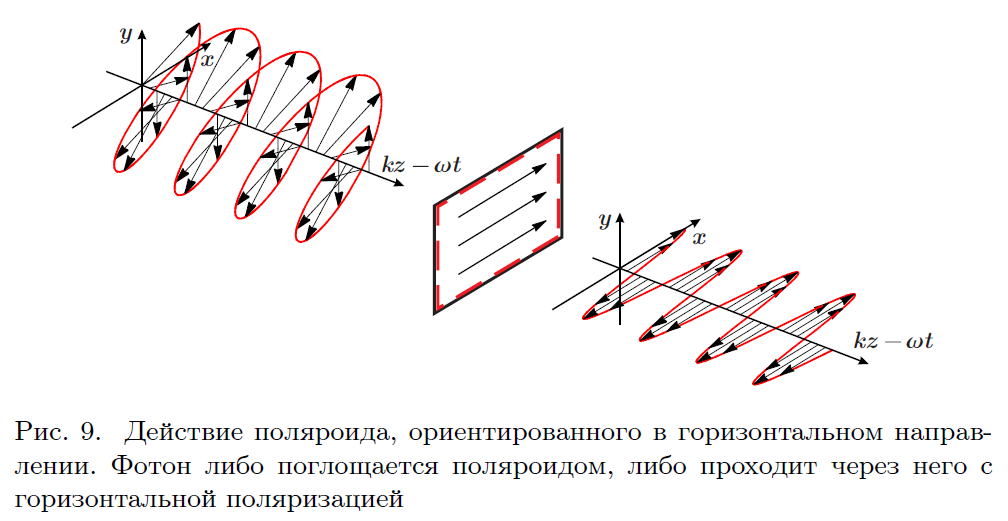

`Мы видим, что норма вектора `$P|\psi \rangle$` равна `$|c_1 |^2 \le 1$`. Это указывает на поглощение фотона поляроидом. Действительно, ``опыт показывает``, что вероятность зафиксировать фотон детектором в точности равна `$|c_1 |^2$`. С другой стороны, эта вероятность есть не что иное, как `$|\langle H|\psi \rangle |^2$`. Вероятность поглощения равна `$1-|c_1 |^2 =|c_2 |^2 =|\langle V|\psi \rangle |^2$`.`

`Для прояснения связи физики и математики вспомним математическую ``задачу поиска собственных векторов и собственных значений`` матрицы. Для заданной матрицы ``A`` требуется найти числа � и ненулевые векторы `$|f\rangle$` такие, что`

$A|f\rangle =\lambda |f\rangle$                     (15)

`Поиск собственных значений заключается в решении уравнения `$\mathrm{det}\left(A-\lambda \;I\right)=0$`, а затем решения системы уравнений `$\left(A-\lambda I\right)|f\rangle =0$`.`

`Матрица ``P`` эрмитова, е собственные значения равны 1 и 0, соответствующие им собственные векторы � это векторы `$|H\rangle$` и `$|V\rangle$`.`

`Cреднее значение физической наблюдаемой прохождение фотона есть математическое ожидание:`


$$1�\cdot \left(\mathrm{вероятность}\;\mathrm{исхода}\;"1"\right)+0�\;\left(\mathrm{вероятность}\;\mathrm{исхода}\;\mathrm{"0"}\right)=$$



$$=1\cdot |c_1 |^2 +0\cdot |c_2 |^2 =\left\lbrack \begin{array}{cc}
c_1^*  & c_2^* 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
c_1 \\
c_2 
\end{array}\right\rbrack =\langle \psi |P|\psi \rangle \equiv \langle P\rangle$$


`Запись `$\langle P\rangle$` означает среднее значение наблюдаемой, где усреднение ведется по результатам измерений для фиксированного состояния фотона j i (много фотонов, каждый из которых находится в состоянии j i, пропускаем через поляроид и смотрим, щ лкнул ли детектор). Такие средние называют средними по состоянию j i, что и подразумевает запись hPi � h jPj i. Саму измеряемую величину прохождение фотона тоже можно обозначить буквой Pфиз.вел. = f1; 0g, которая может принимать два значения. Тогда`